# Signal Source Separation Using W-Net Architecture

This example shows how to separate two mixed signal sources using a deep learning network. Source separation is a common and complex signal processing problem that finds use in audio, vibration analysis, and biomedical applications. It consists of separating the signal components of a signal mixture when only the mixture is available. 

An important source separation problem consists of discerning fetal and maternal electrocardiogram (ECG) signals present in noninvasive measurements taken on the abdominal area of a pregnant patient. This is an important problem because, if solved correctly, it can allow physicians to monitor the fetal ECG with minimum risk. Fetal cardiac monitoring and assessment during pregnancy are used for the early detection of fetal cardiac conditions.

This example uses simulated noninvasive abdominal ECG measurements on pregnant patients to illustrate how to solve the difficult problem of separating the fetal ECG and maternal ECG signals using a deep network. The source separation deep learning architecture used in this example is not limited to ECG signals and can be used in many other applications.

## FECGSYN Data Set

This example uses the FECGSYN PhysioNet data set [[1](about:blank<#M_317EA6F7%3E)], [[2](about:blank<#M_F2EA8770%3E)], which contains simulated adult and noninvasive fetal ECG signals. The data is generated using the FECGSYN simulator [[3](about:blank<#M_D7F292E0%3E)]. The simulator represents maternal and fetal hearts as punctual dipoles with different magnitudes and spatial positions. It obtains fetal–maternal mixtures by treating each abdominal signal and noise component as an individual source whose signal is propagated onto the observational points (electrodes). This database is able to provide separate waveform files for each signal source, making it ideal to test a source separation deep learning model.

The FECGSYN consists of simulated ECG signals corresponding to ten different subjects. For each subject, simulations produced a fetal ECG (`fECG`), a maternal ECG (`mECG`), and two noise sources, all sampled at a rate of 250 Hz for five minutes. The original data set repeats simulations five times for five different SNR levels, for 34 ECG channels or "electrodes", and for five different measurement scenarios or cases. In this example we use a subset of the data set and consider all ten subjects, a single channel (channel 19 from the original data set), four SNR levels (3, 6, 9, and 12 dB), and three different measurement cases labeled C0, C1, and C3. As mentioned before, the simulation was repeated over five iterations for each combination of subject, SNR value, and measurement case, yielding a total of 10 subjects × 4 SNRs × 3 cases × 5 iterations = 600 files. There are three different measurement cases:

- Case 0 (C0) — Baseline ECG signals

- Case 1 (C1) — Fetal movement + C0

- Case 3 (C3) — Signals with varying maternal and fetal heart rates + Noise from uterine contractions

The data set contains one MAT-file for each combination of subject, SNR level, iteration, and measurement case. The filenames use the format Ij_Ck.mat, where `j` is the iteration number (1 to 5) and `k` is the measurement case identifier (0, 1, 3). Each MAT-file contains these variables:

- `mECG` — Maternal ECG signal

- `fECG` — Fetal ECG signal

- `mECG_QRS` — QRS peak locations for the maternal ECG signal as annotated by an expert system

- `fECG_QRS` — QRS peak locations for the fetal ECG signal as annotated by an expert system

- `noise1` — First noise source

- `noise2` — Second noise source

All signals have been bandpass filtered into the frequency range from 5 Hz to 90 Hz.

The abdominal ECG signal (`aECG`) for each file is computed as the following mixture:

The `mECG_QRS` and `fECG_QRS` variables contain QRS peak locations of the maternal and fetal ECG signals and can be used to validate the efficacy of a source separation algorithm to identify correct heartbeat locations in time.

% Download test data set
testDatasetZipFile = matlab.internal.examples.downloadSupportFile('SPT','data/fetal-ecg-source-separation-testData.zip');
testDatasetFolder = fullfile(tempdir,'fetal-ecg-source-separation-testData');
if ~exist(testDatasetFolder,'dir')
    unzip(testDatasetZipFile,testDatasetFolder);
end

Create a signal datastore to access the files in the test data set. Specify the names of the variables that you want the datastore to read from each file.

testDS = signalDatastore(testDatasetFolder,IncludeSubfolders=true, ...
    SignalVariableNames=["mECG" "fECG" "noise1" "noise2" "mECG_QRS" "fECG_QRS"]);

Plot the first 2048 samples of the ECG signals for case C1 and SNR of 3 dB. Overlay the annotated QRS peaks for each signal.

idx = contains(testDS.Files,fullfile("snr03dB","I1_C1.mat"));
sds3dBC1 = subset(testDS,idx);

data = preview(sds3dBC1);
[mECG,fECG,noise1,noise2,mECG_QRS,fECG_QRS] = data{:};

% Abdominal ECG mixture
aECG = mECG(1:2048) + fECG(1:2048) + noise1(1:2048) + noise2(1:2048);

figure
subplot(3,1,1)
plot(aECG)
xline(fECG_QRS(1:50),":",Color="#77AC30")
xline(mECG_QRS(1:50),":",Color="#D95319")
axis([0 2048 -0.6 1])
title("aECG (red = mECG QRS peaks, green = fECG QRS peaks)")

subplot(3,1,2)
plot(fECG(1:2048))
xline(fECG_QRS(1:50),":",Color="#77AC30")
axis([0 2048 -0.6 1])
title("fECG")

subplot(3,1,3)
plot(mECG(1:2048))
xline(mECG_QRS(1:50),":",Color="#D95319")
axis([0 2048 -0.6 1])
title("mECG")

Notice the large difference in scale between the `mECG` and `fECG` signals.

## W-Net Architecture for Source Separation

This example uses a so-called W-Net architecture to perform source separation [[4](about:blank<#M_C4CF9244%3E)]. W-Net consists of two U-Net autoencoders [[5](about:blank<#M_32BFA8D3%3E)] that have been modified to operate on 1-D signal inputs. A U-Net autoencoder is a deep network that encodes signal features reducing its size at each step and then decodes the features to recreate the original input signal. You can think of the encoder branch of the autoencoder as a feature extraction branch. The main idea of the W-Net architecture is to have one auto encoder to reproduce an `fECG` signal (`fECG` autoencoder) and another to reproduce an `mECG` signal (`mECG` autoencoder) when the input to the autoencoders is set to an `aECG` mixture. The connection between the two autoencoders happens in the encoding branches. You subtract the features obtained by the `mECG` autoencoder from the features obtained by the `fECG` autoencoder, effectively achieving separation of the `mECG` component from the `aECG` input and yielding the desired separated `fECG` signal. This figure shows the architecture in detail.

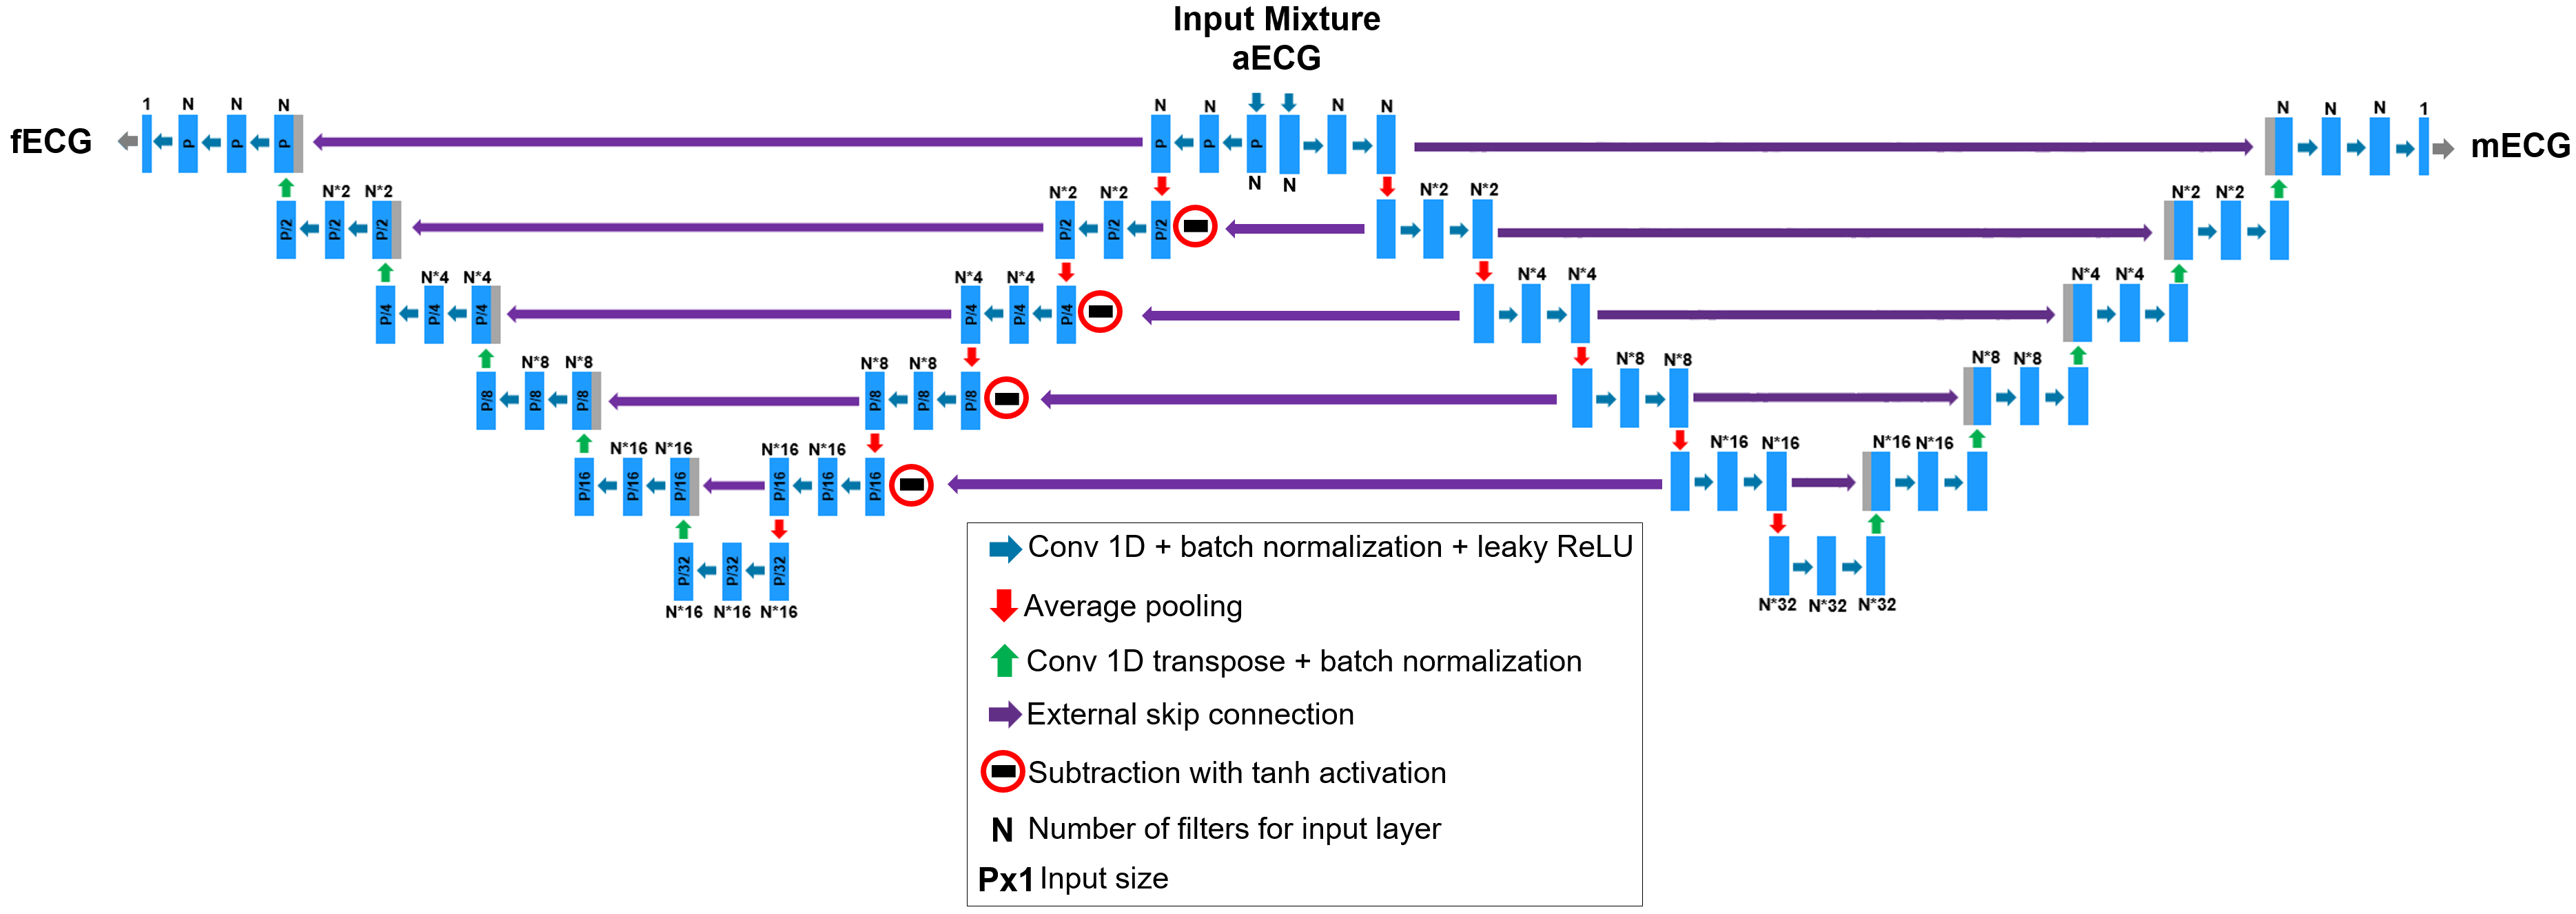

Load a pretrained model if `trainNetworkFlag` is `false`. The model file will be unzipped to the `tempdir` directory. If you want the model at a different location, change `modelFolder` to the desired value.

% Download the pre-trained network
modelZipFile = matlab.internal.examples.downloadSupportFile('SPT','data/fetal-ecg-source-separation-model.zip');
modelFolder = fullfile(tempdir,'fetal-ecg-source-separation-model');
if ~exist(modelFolder,'dir')
    unzip(modelZipFile,modelFolder);
end
modelFile = fullfile(modelFolder,'fetal-ecg-source-separation-model','Model.mat');
load(modelFile)

## Test Model

To test the trained network, use the previously created test datastore, `testDS`, that points to data from subject 10. This datastore reads the ECG data and the QRS peak location annotations so they can be used to validate the predicted `mECG` and `fECG` signals. As was done for the training datastore, transform the test datastore to get segmented and normalized `aECG`, `mECG`, and `fECG` signals.

testDS = transform(testDS,@(d,f)getECGSegments(d,segmentLength));
idx = contains(string(testDS.UnderlyingDatastores{1}.Files),fullfile("snr09dB","I3_C1.mat"));
ds = subset(testDS,idx);
data = read(ds);
mECG_QRS = data(:,4);
fECG_QRS = data(:,5);
[aECGbatch,mECGbatch,fECGbatch] = processMB(data(:,1),data(:,2),data(:,3));

% Move the aECGbatch into a dlarray and call the predict method of the
% trained network to estimate the source signals
dlaECG = dlarray(aECGbatch,"CBT");
[dlpred_fECG,dlpred_mECG] = predict(wNet,dlaECG);
pred_fECG = squeeze(extractdata(dlpred_fECG))';
pred_mECG = squeeze(extractdata(dlpred_mECG))';
pred_fECG = pred_fECG(:);
pred_mECG = pred_mECG(:);

Plot a few samples of the predicted waveforms. Overlay the annotated true QRS peaks using dotted lines.

figure
subplot(2,1,1)
plot(pred_fECG(1:2048))
xline([fECG_QRS{1}; fECG_QRS{2}],":k")
title("Predicted fECG")
axis([1 2048 -1.5 1])

subplot(2,1,2)
plot(pred_mECG(1:2048))
xline([mECG_QRS{1}; mECG_QRS{2}],":k")
title("Predicted mECG")
axis([1 2048 -1 2])

Plot the mean absolute deviation of the estimated `fECG` and `mECG` signals for all measurements of subject 10 using the [`computeErrorsForAllCases`](about:blank<#H_E8AB068D%3E) function.

computeErrorsForAllCases(wNet,testDS)

The errors do not decrease monotonically with SNR because of the variability of all the different combinations of noise, fetal movement, and heart-rate irregularities.

This example implements a W-Net architecture suitable for source separation of a mixture of two signals. The example analyzes the performance of the network using synthetic signal mixtures comprised of fetal and maternal ECG waveforms. The example shows that, in most scenarios, the network does a good job separating ECG signals and estimating correct waveform shapes and QRS peak locations.

## Compress the network using Pruning and Projection techniques

The `compressNetworkUsingProjection` function uses principal component analysis (PCA) to identify the subspace of learnable parameters that result in the highest variance in neuron activations by analyzing the network activations using a data set of training data. This analysis requires only the predictors of the training data to compute the network activations. It does not require the training targets.

The PCA step can be computationally intensive. If you expect to compress the same network multiple times (for example, when exploring different levels of compression), then perform the PCA step first and reuse the resulting `neuronPCA` object.

Create a mini-batch queue containing the training data. To create a mini-batch queue from in-memory data, convert the sequences to an array datastore.